afirst = [0.105 0 0.003 0
    0 1 0 0 
    0.09 0 0.39 0
    0 0 0 1];
a1first = inv(afirst);
a3first = [0 0 0 0 
    1 0 0 0
    0 0 0 0.6*9.8
    0 0 1 0];
Afirst = a1first*a3first

Afirst =          0         0         0   -0.4336
    1.0000         0         0         0
         0         0         0   15.1770
         0         0    1.0000         0


b = [4
    0
    0
    0];
Bfirst = a1first*b

Bfirst =    38.3481
         0
   -8.8496
         0


C = [0 1 0 0;0 0 0 1;1 0 0 0];
D = [0;0;0];
sys1 = ss(Afirst,Bfirst,C,D)

sys1 =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        0  -0.4336
   x2        1        0        0        0
   x3        0        0        0    15.18
   x4        0        0        1        0
 
  B = 
          u1
   x1  38.35
   x2      0
   x3  -8.85
   x4      0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
   y3   1   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.




asecond = [0.141 0 0.045 0
    0 1 0 0 
    0.45 0 0.75 0
    0 0 0 1];
a1second = inv(asecond);
a3second = [0 0 0 0 
    1 0 0 0
    0 0 0 3*9.8
    0 0 1 0];
Asecond = a1second*a3second

Asecond =          0         0         0  -15.4737
    1.0000         0         0         0
         0         0         0   48.4842
         0         0    1.0000         0


Bsecond = a1second*b

Bsecond =    35.0877
         0
  -21.0526
         0


sys2 = ss(Asecond,Bsecond,C,D)

sys2 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       0  -15.47
   x2       1       0       0       0
   x3       0       0       0   48.48
   x4       0       0       1       0
 
  B = 
           u1
   x1   35.09
   x2       0
   x3  -21.05
   x4       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
   y3   1   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.




athird = [0.141 0 0.03 0
    0 1 0 0 
    0.45 0 0.5 0
    0 0 0 1];
a1third = inv(athird);
a3third = [0 0 0 0 
    1 0 0 0
    0 0 0 3*9.8
    0 0 1 0];
Athird = a1third*a3third

Athird =          0         0         0  -15.4737
    1.0000         0         0         0
         0         0         0   72.7263
         0         0    1.0000         0


Bthird = a1third*b

Bthird =    35.0877
         0
  -31.5789
         0


sys3 = ss(Athird,Bthird,C,D)

sys3 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       0  -15.47
   x2       1       0       0       0
   x3       0       0       0   72.73
   x4       0       0       1       0
 
  B = 
           u1
   x1   35.09
   x2       0
   x3  -31.58
   x4       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
   y3   1   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.




% eig(A)
% 
% %Check whether the system is controllable 
% Qc = ctrb(A,B);
% rank(Qc)
% %Check whether the system is observable 
% Qb = obsv(A,C);
% rank(Qb)
% 
% Edit A,B to check above.

Q = [1 0 0 0
    0 5 0 0
    0 0 1 0
    0 0 0 5];
R = 0.0001;

Kfirst = lqr(Afirst,Bfirst,Q,R)

Kfirst = 	1.0e+03 *

   -0.2160   -0.2236   -1.3818   -5.3559


Acfirst = Afirst-Bfirst*Kfirst;

Ksecond = lqr(Asecond,Bsecond,Q,R)

Ksecond = 	1.0e+03 *

   -0.1744   -0.2236   -0.4857   -2.9844


Acsecond = Asecond-Bsecond*Ksecond;

Kthird = lqr(Athird,Bthird,Q,R)

Kthird = 	1.0e+03 *

   -0.1632   -0.2236   -0.3313   -2.4326


Acthird = Athird-Bthird*Kthird;

x0_0 = [0;0;0;0];
x0_30 = [0;0;0;pi*30/180];

t = 0:0.05:10;
u = zeros(size(t));

% % y0: initially  0 degree and no input;
% [y0,x] = lsim(A,B,C,D,u,t,x0_0);
% plot(t,y0)
% 
% Edit A,B to check above.

% y: initially 30 degree and lqr input;
[yfirst,xfirst] = lsim(Acfirst,Bfirst,C,D,u,t,x0_30);
[ysecond,xsecond] = lsim(Acsecond,Bsecond,C,D,u,t,x0_30);
[ythird,xthird] = lsim(Acthird,Bthird,C,D,u,t,x0_30);

u1 = xfirst*Kfirst'

u1 = 	1.0e+03 *

   -2.8043
    0.0034
    0.0027
    0.0021
    0.0016
    0.0013
    0.0010
    0.0007
    0.0005
    0.0004


u2 = xsecond*Ksecond'

u2 = 	1.0e+03 *

   -1.5626
    0.0020
    0.0016
    0.0012
    0.0009
    0.0007
    0.0005
    0.0003
    0.0002
    0.0001


u3 = xthird*Kthird'

u3 = 	1.0e+03 *

   -1.2737
    0.0014
    0.0011
    0.0009
    0.0007
    0.0005
    0.0004
    0.0002
    0.0002
    0.0001


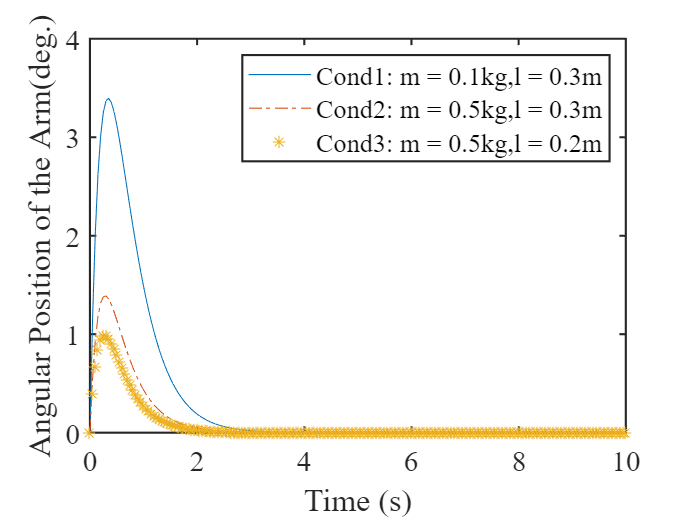


plot(t,yfirst(:,1));
hold on;
plot(t,ysecond(:,1),'-.');
hold on;
plot(t,ythird(:,1),'*');
hold on;
legend('Cond1: m = 0.1kg,l = 0.3m','Cond2: m = 0.5kg,l = 0.3m','Cond3: m = 0.5kg,l = 0.2m');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);
ylabel('Angular Position of the Arm(deg.)');
xlabel('Time (s)');
hold off;

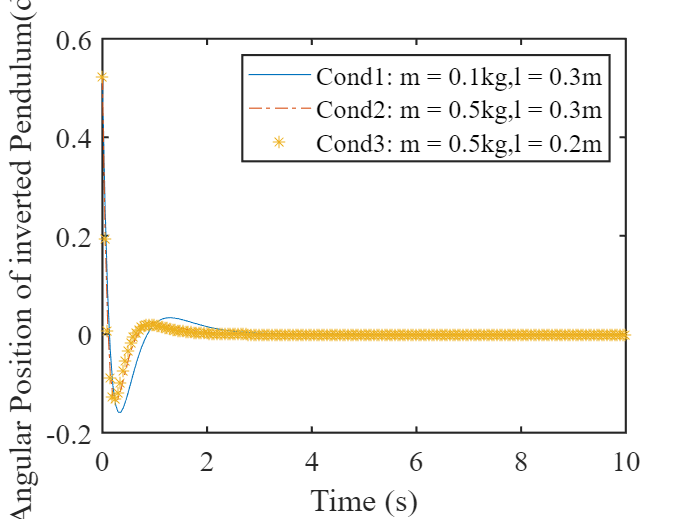



plot(t,yfirst(:,2));
hold on;
plot(t,ysecond(:,2),'-.');
hold on;
plot(t,ythird(:,2),'*');
hold on;
legend('Cond1: m = 0.1kg,l = 0.3m','Cond2: m = 0.5kg,l = 0.3m','Cond3: m = 0.5kg,l = 0.2m');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);
ylabel('Angular Position of inverted Pendulum(deg.)');
xlabel('Time (s)');
hold off;

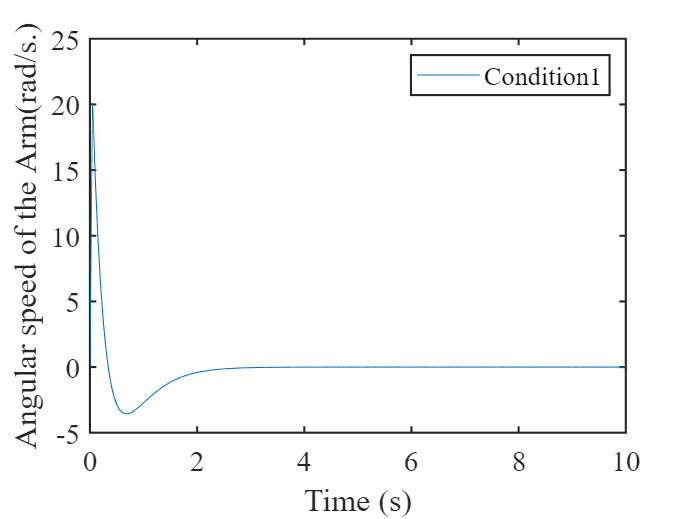


% The speed and torque can not be seen clearly if they are in the same plot
% So it is drawn individually

plot(t,yfirst(:,3))
legend('Condition1')
ylabel('Angular speed of the Arm(rad/s.)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);

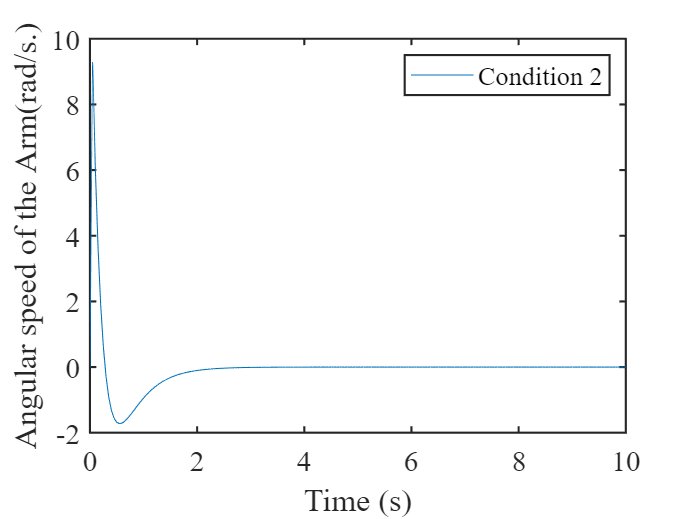


plot(t,ysecond(:,3))
legend('Condition 2')
ylabel('Angular speed of the Arm(rad/s.)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);

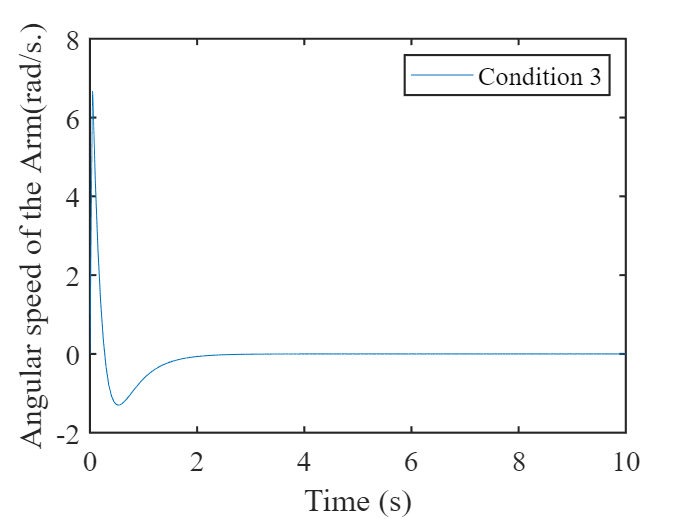


plot(t,ythird(:,3))
legend('Condition 3')
ylabel('Angular speed of the Arm(rad/s.)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);

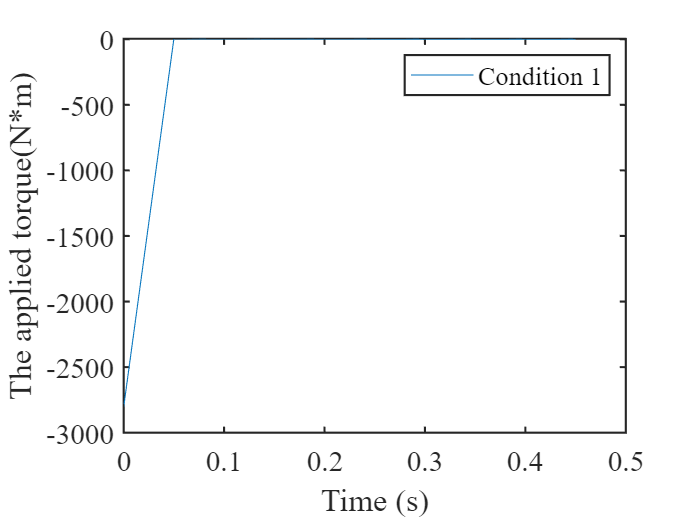



plot(t(1:10),u1(1:10))
legend('Condition 1')
ylabel('The applied torque(N*m)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);

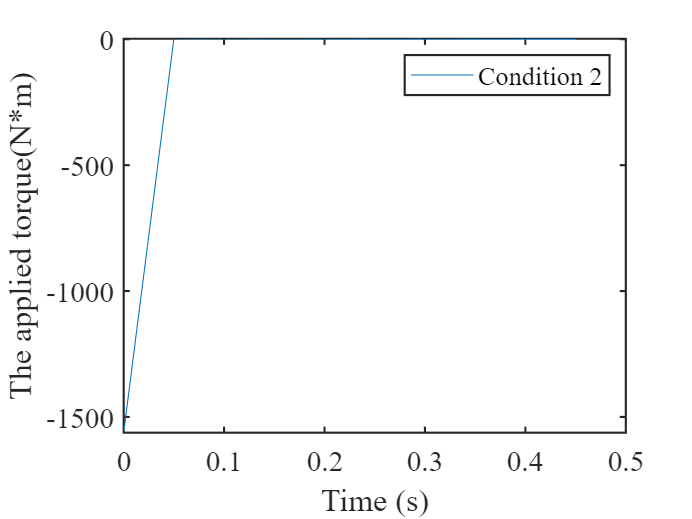


plot(t(1:10),u2(1:10))
legend('Condition 2')
ylabel('The applied torque(N*m)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);

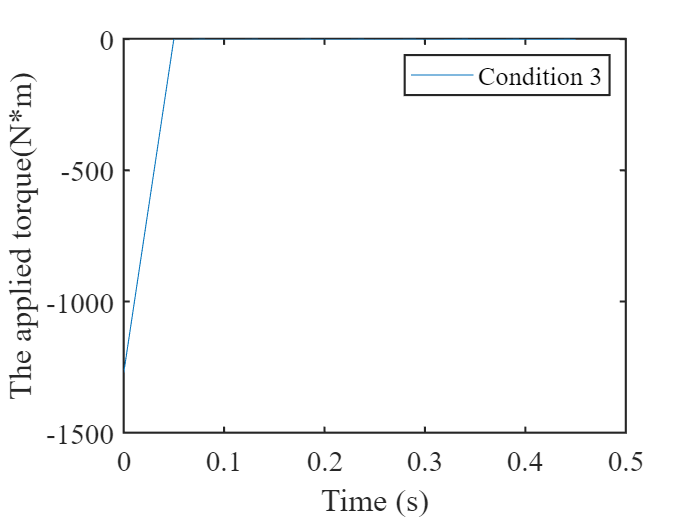


plot(t(1:10),u3(1:10))
legend('Condition 3')
ylabel('The applied torque(N*m)');
xlabel('Time (s)');
set(gca, 'Fontname', 'Times New Roman','FontSize',14,'linewidth',1);